%calculating the mean first passage time using Gillespie simulations
%to investigate effect of branch migration domain length on RNA/DNA TMSD
%kinetics including spontaneous incumbent dissociation

%b = 20 %define branch migration domain length
g = 2 %define invader toehold length

g = 2


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,30)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(30, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(30, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 30)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 30)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,30)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    
    %define forward and reverse rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    
    first_pass_time = zeros(1,N)
    
    %create arrays of forward and reverse rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
        
        %define spontaneous incumbent dissociation rate
        Koff = [0, 0]; 
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
    
        %define spontaneous incumbent dissociation rate
        Koff = [repmat(0, [1, g+1])];
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])      
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition
    Poff = Koff./totalrate; %define probability of spontaneous incumbent dissociation
    Pb = 1- (Pf + Poff); %define probability of reverse transition
    %loop through simulations
    for n = 1:N 
        state = 1; %define initial state
        t = 0; %define initial time
        %restrict states to what can be reached
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            prob = rand();
            %select transition
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b; %update state for spontaneous incumbent dissociation
            else 
                state = state -1; %update state backwards
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(b-9,n) = first_pass_time(n);
        ind_k_eff(b-9,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(b-9) = std(ind_first_pass_time(b-9, :))/sqrt(N); %calculate standard error
    std_err_k_eff(b-9) = std(ind_k_eff(b-9, :))/sqrt(N);
    std_err_log_k(b-9) = std(log10(ind_k_eff(b-9,:))/sqrt(N));
    avr_first_pass_time(b-9) = mean(first_pass_time) %calculate first passage time
    k_eff(b-9) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205    3.7985         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205    3.7985    6.7897         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205    3.7985    6.7897    4.2545         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205    3.7985    6.7897    4.2545    3.4846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563         0         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663         0         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204         0         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918         0         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281         0         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823         0         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565         0         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043         0         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043  618.8705         0         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778    3.2317         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043  618.8705  458.8849         0         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778    3.2317    4.3584         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043  618.8705  458.8849  658.7281         0


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778    3.2317    4.3584    3.0362         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043  618.8705  458.8849  658.7281  310.8236


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778    3.2317    4.3584    3.0362    6.4345


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198


avr_first_pass_time =   475.0665  316.4291  526.5258  294.5621  470.0956  573.9499  336.3399  560.3785  453.0636  575.6838  303.8504  336.2394  269.6297  305.1742  349.2377  340.1578  373.7599  618.6670  387.8563  303.6663  575.5204  420.7918  264.3281  361.4823  265.7565  529.4043  618.8705  458.8849  658.7281  310.8236


k_eff =     4.2099    6.3205    3.7985    6.7897    4.2545    3.4846    5.9464    3.5690    4.4144    3.4741    6.5822    5.9481    7.4176    6.5536    5.7268    5.8796    5.3510    3.2328    5.1565    6.5862    3.4751    4.7529    7.5664    5.5328    7.5257    3.7778    3.2317    4.3584    3.0362    6.4345


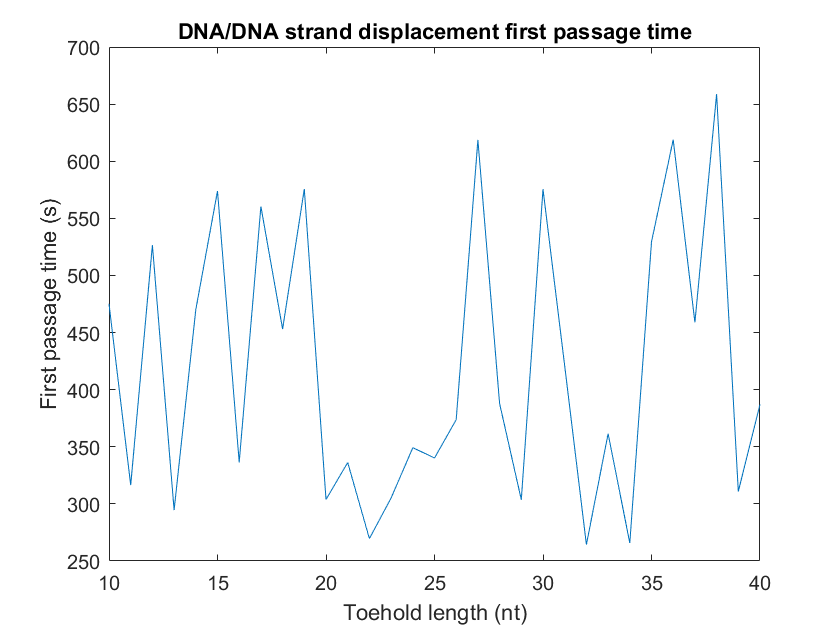

plot(10:40, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

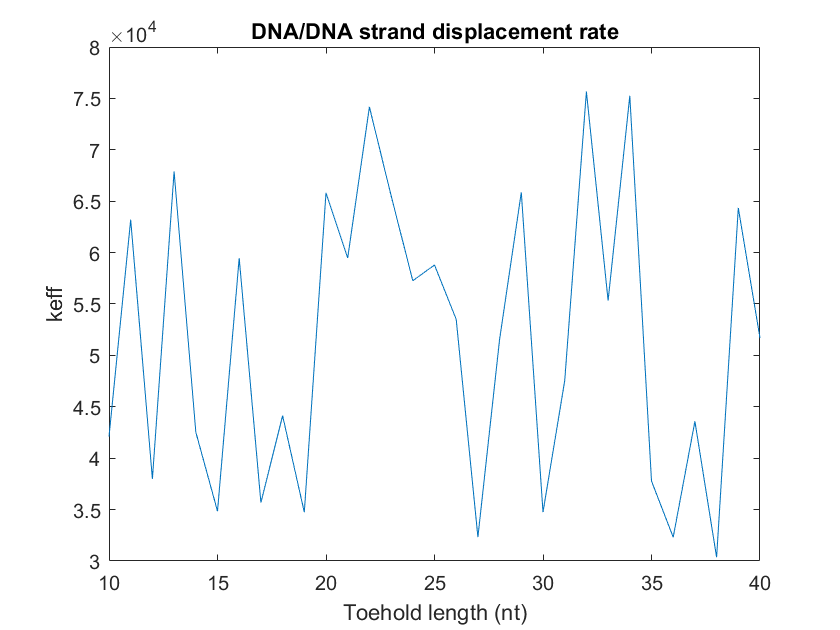


plot(10:40, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

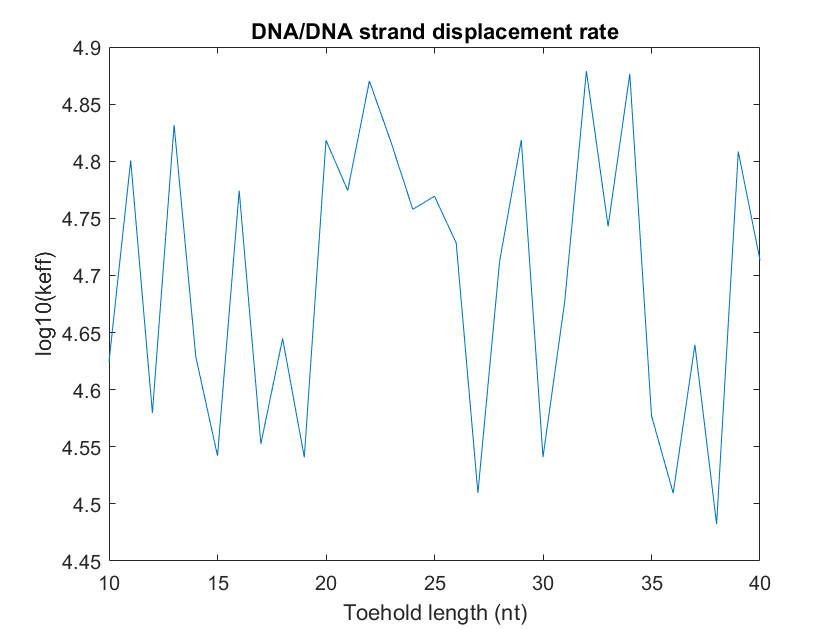


plot(10:40, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

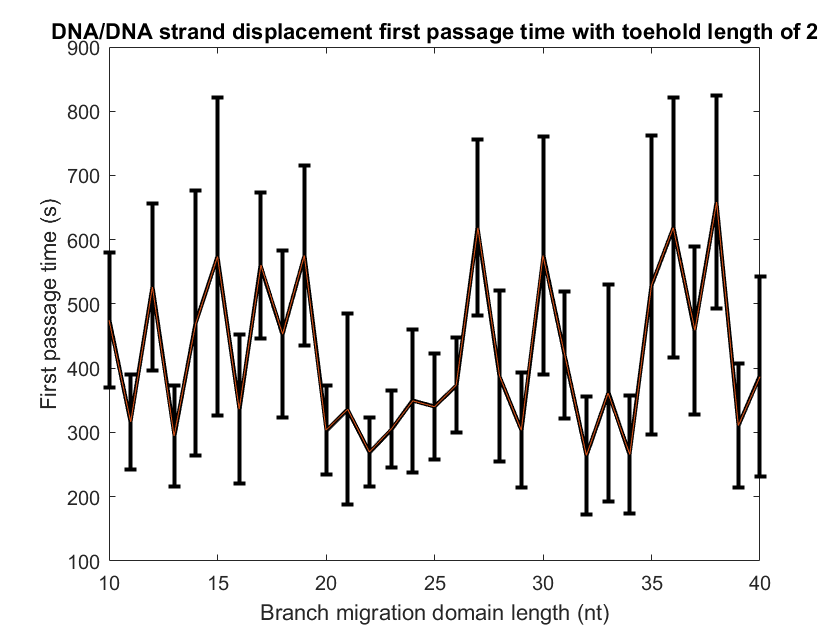


errorbar(10:40, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(10:40, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

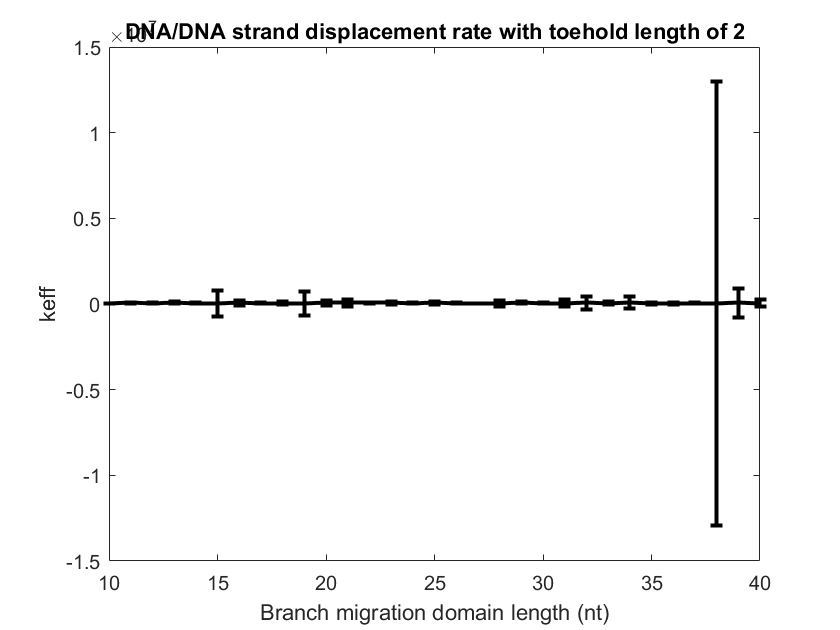


errorbar(10:40, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

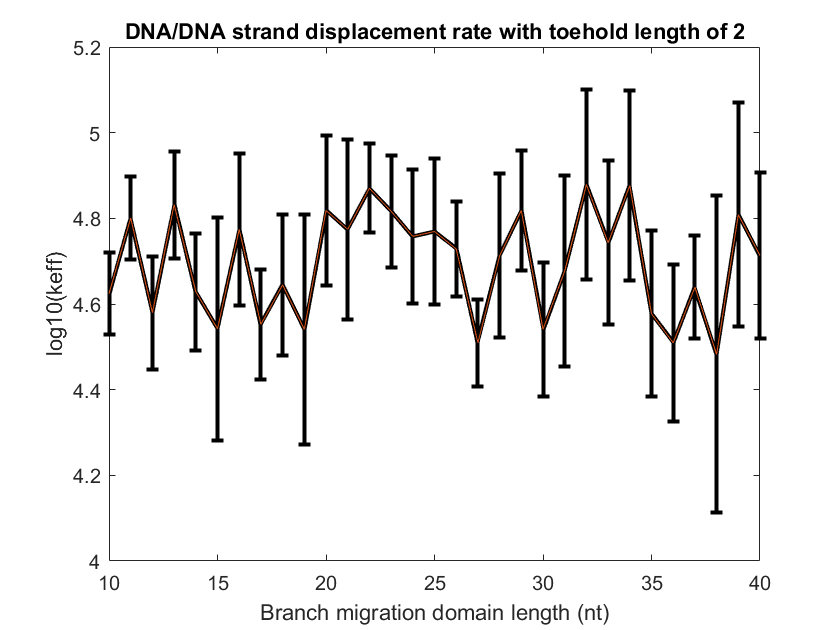


errorbar(10:40, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(10:40, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off